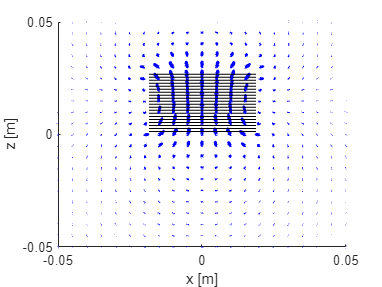

clear
clf
%%Graph parameters
xmin=-0.05;
xmax=0.05;
ymin=xmin;
ymax=xmax;
zmin=-0.05;
zmax=-zmin;

%%inputs
u0=4*pi*10^(-7); %permability
AWG=16;
AWG_d=0.005*92^((36-AWG)/39); %diameter [inches]
insul_thick=0.001; %insulation thickness [inches]
Current=30.0; %[amps]
R0=0.5; %radius to outside of barrel
num_L=5; %number of Layers
num_T=100; %number of Turns overall
segments=50; %points per loop
dx=0.005; %B field step size
%b field calculated by radius of each loop

%%calculations
%spacing is determined initally to be a wire diameter + 2 insul thick
spacing=(AWG_d+2*insul_thick)*(25.4/1000); %[inches->m]
%zmax=0.0+spacing*num_T/num_L-zmin;
%%determine circumferences
%circumferences=zeros(1,num_L)
radii=zeros(1,num_L);
radii(1,1)=(R0+insul_thick+AWG_d/2)*(25.4/1000);
%circumferences(1,1)=2*pi*(R0+insul_thick+AWG_d/2)
for n=2:num_L
    radii(1,n)=(R0+insul_thick+AWG_d/2+2*(insul_thick+AWG_d/2)*(n-1))*(25.4/1000);
    %circumferences(1,n)=2*pi*(R0+insul_thick+AWG_d/2+2*(insul_thick+AWG_d/2)*n)
end
%%3d space setup
theta=linspace(0,2*pi,segments);
Rx=zeros(num_L,segments); %2d arrays of layers x points
Ry=zeros(num_L,segments); %2d arrats of layers x points
Rz=zeros(num_T/num_L,segments); %2d array of layes x points

%iterate to assign radii of circles
for n=1:num_L %for all raddii
    for t=1:segments %fill data points
        Rx(n,t)=radii(1,n)*cos(theta(1,t));
        Ry(n,t)=radii(1,n)*sin(theta(1,t));
    end
end

%iterate to assign height posistion of circles unique as it has to traverse
%all levels

for k=1:num_T/num_L %for all heights
    for t=1:segments %fill data points
        Rz(k,t)=spacing*k;
    end    
end

for k=1:num_T/num_L %for all heights
    for n=1:num_L %for all raddii
        plot3(Rx(n,:),Ry(n,:),Rz(k,:),'--k')
        hold on
    end
end

xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')
view([0,0])

%above here has worked

%%Now B field through biot savart law and derivative estimates

%%map 3d space
x=xmin:dx:xmax; %set array of x
y=ymin:dx:ymax; %set array of y
z=zmin:dx:zmax; %set array of z
%this range to calculate b field
[X,Y,Z]=meshgrid(x,y,z); %creates 3d grid off of bounds

Bx=zeros(size(x));
By=zeros(size(y));
Bz=zeros(size(z));
%need to sum all b fields together

%go at each height, then each ring and each time solve b dield
for k=1:num_T/num_L %for all heights
    for n=1:num_L %for all raddii
        Rx_1=Rx(n,:);
        Ry_1=Ry(n,:);
        Rz_1=Rz(k,:);

        Points=transpose([Rx_1;Ry_1;Rz_1]); %rotate matrix


        
        %%calculations

        %determine B field by steps of dx

        for t=1:segments-1 %fill data points
            Rx_1=X-Points(t,1);
            Ry_1=Y-Points(t,2);
            Rz_1=Z-Points(t,3);
            R=sqrt(Rx_1.^2+Ry_1.^2+Rz_1.^2); %overall distance to point
            R=R.*(R>=dx)+dx*(R<dx); %rounding for step size

            dLx=Points(t+1,1)-Points(t,1);
            dLy=Points(t+1,2)-Points(t,2);
            dLz=0;

            %components at each point by biot-savart law
            Bx=Bx+u0*Current/(4*pi)*(dLy.*Rz_1-dLz.*Ry_1).*R.^(-3);
            By=By+u0*Current/(4*pi)*(dLz.*Rx_1-dLx.*Rz_1).*R.^(-3);
            Bz=Bz+u0*Current/(4*pi)*(dLx.*Ry_1-dLy.*Rx_1).*R.^(-3);
            
        end  
    end
end
quiver3(X,Y,Z,Bx,By,Bz,'--b','LineWidth',2)
axis([xmin xmax ymin ymax zmin zmax])

% % 
% % %This is a simulation to model a video found to do stacked loops such as a
% % %solenoid found at 
% % %https://www.youtube.com/watch?v=mJfdboA4iME&ab_channel=KurtOwen
% % % clear
% % % clf
% % % %%set parameters
% % % I=1.0; %[Amps]
% % % u0=4*pi*10^(-7); %permability
% % % 
% % % nR=50; %number of segments
% % 
% % %%graph window
% % % xmin=-0.02;
% % % xmax=0.02;
% % % ymin=xmin;
% % % ymax=xmax;
% % % zmin=xmin;
% % % zmax=xmax;
% % % dx=0.005; %step size for grid
% % % 
% % % nloops=16; %number of loops [per layer]
% % % spacing=.8*(zmax-zmin)/nloops; %will be swaped for wire parameter spacing
% % % zlow=-0.5*((nloops-1)*spacing);
% % 
% % % %%initialize vectors
% % % theta=linspace(0,2*pi,nR+1);
% % % Rx=R0*cos(theta); %x points on loops by radius
% % % Ry=R0*sin(theta); %y points on loops by radius
% % % Rz=zlow*ones(1,nR+1); 
% % % 
% % % Points=transpose([Rx;Ry;Rz]); 
% % % 
% % % x=xmin:dx:xmax;
% % % y=ymin:dx:ymax;
% % % z=zmin:dx:zmax;
% % % 
% % % [X,Y,Z]=meshgrid(x,y,z); %creates 3d grid
% % % 
% % % %%calculations
% % % Bx=zeros(size(x));
% % % By=zeros(size(y));
% % % Bz=zeros(size(z));
% % % for jt=1:nloops %for number of turns per layer
% % %     for it=1:nR
% % %         Rx=X-Points(it,1);
% % %         Ry=Y-Points(it,2);
% % %         Rz=Z-Points(it,3);
% % % 
% % %         R=sqrt(Rx.^2+Ry.^2+Rz.^2); %overall distance to point
% % %         R=R.*(R>=dx)+dx*(R<dx); %rounding for step size
% % % 
% % %         dLx=Points(it+1,1)-Points(it,1);
% % %         dLy=Points(it+1,2)-Points(it,2);
% % %         dLz=0;
% % % 
% % %         %components at each point by biot-savart law
% % %         Bx=Bx+u0*I/(4*pi)*(dLy.*Rz-dLz.*Ry).*R.^(-3);
% % %         By=By+u0*I/(4*pi)*(dLz.*Rx-dLx.*Rz).*R.^(-3);
% % %         Bz=Bz+u0*I/(4*pi)*(dLx.*Ry-dLy.*Rx).*R.^(-3);
% % %     end
% % %     
% % %     axis([xmin xmax ymin ymax zmin zmax])
% % %     hold on
% % %     quiver3([-1.1*R0,1,1*R0],[.2*R0,-.2R0])
% % % end
% % % quiver3(X,Y,Z, Bx,By,Bz,'b')
% % % hold off
% % % rotate3d on
% % % 
% % % xlabel('x [m]')
% % % ylabel('y [m]')
% % % zlabel('z [m]')
% % % view(-30,15)
% % % title('b-field visualization')
